#### Wymagane toolbox'y:

- Mapping Toolbox

#### Makra

function maxs = avg_maximums_month(tables)
    maxs = zeros(length(tables), 12);

    for i = 1:length(tables)
        table = tables{i};

        for j = 1:12
            maxs(i, j) = round(mean(table(month(table.date) == j, "max_temp").max_temp), 1);
        end
    end
end

function mins = avg_minimums_month(tables)
    mins = zeros(length(tables), 12);

    for i = 1:length(tables)
        table = tables{i};

        for j = 1:12    
            mins(i, j) = round(mean(table(month(table.date) == j, "min_temp").min_temp), 1);
        end
    end
end

function maxs = avg_maximums_day(table)
    maxs = zeros(1, 365);
    table = table(~(month(table.date) == 2 & day(table.date) == 29), :);

    for i = 1:365
        maxs(i) = round(mean(table(day(table.date, 'dayofyear') == i, "max_temp").max_temp), 1);
    end
end

function mins = avg_minimums_day(table)
    mins = zeros(1, 365);
    table = table(~(month(table.date) == 2 & day(table.date) == 29), :);

    for i = 1:365
        mins(i) = round(mean(table(day(table.date, 'dayofyear') == i, "min_temp").min_temp), 1);
    end
end

#### Wczytanie danych z plików CSV

brazil_curitiba = readtable("brazil_curitiba.csv");
colombia_medellin = readtable("colombia_medellin.csv");
brazil_natal = readtable("brazil_natal.csv");
brazil_portoalegre = readtable("brazil_porto-alegre.csv");
ecuador_quito = readtable("ecuador_quito.csv");
brazil_saopaulo = readtable("brazil_sao-paulo.csv");

#### Pokazanie na mapie miejsc, których dotyczą nasze dane

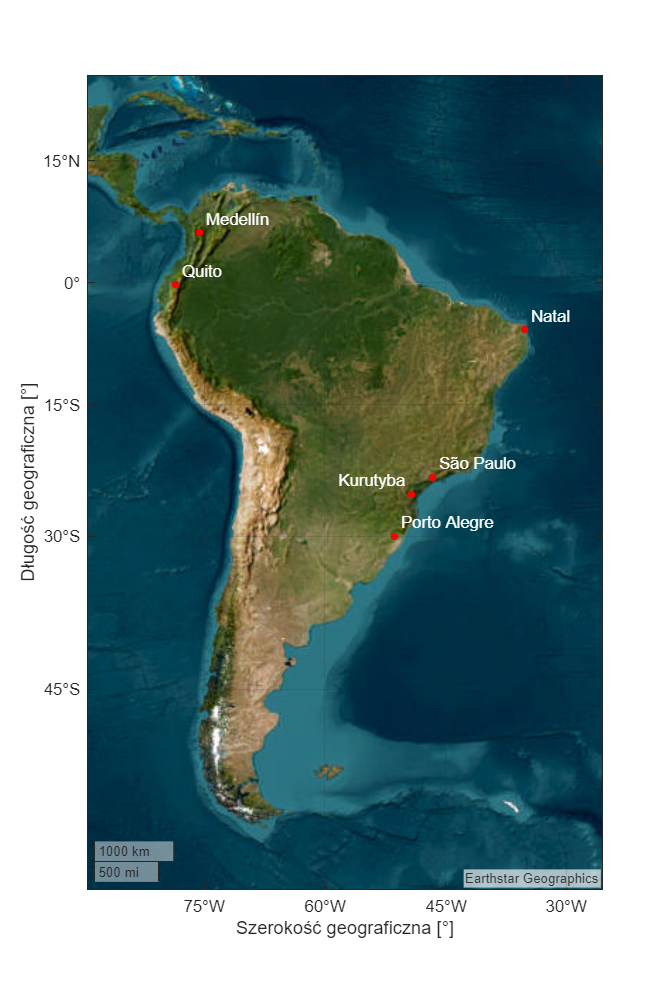

cities = {'Kurutyba', 'Medellín', 'Natal', 'Porto Alegre', 'Quito', 'São Paulo'};
latitudes = [-25.468611, 6.216667, -5.795, -30.039444, -0.25, -23.5];
longitudes = [-49.253333, -75.566667, -35.208889, -51.307778, -78.583333, -46.616667];

figure(1);
set(gcf, 'Position', [100, 100, 800, 1200]);
geobasemap('satellite');
hold on;

geolimits([-60, 25], [-85, -30]);
geoscatter(latitudes, longitudes, 20, 'red', 'filled');

for i = 1:length(cities)
    x = 0.8;
    y = 0.5;
    ha = 'left';

    if strcmp(cities{i}, 'Kurutyba')
        x = -0.8;
        ha = 'right';
    end

    text(latitudes(i) + y, longitudes(i) + x, cities{i}, ...
        'FontSize', 10, 'Color', 'white', ...
        'HorizontalAlignment', ha, 'VerticalAlignment', 'bottom');
end

gx = gca;
gx.LatitudeLabel.String = 'Długość geograficzna [°]';
gx.LongitudeLabel.String = 'Szerokość geograficzna [°]';

hold off;

#### Porównanie średnichm, maksymalnych i minimalnych temperatur w każdym mieście dla poszczególnych miesięcy

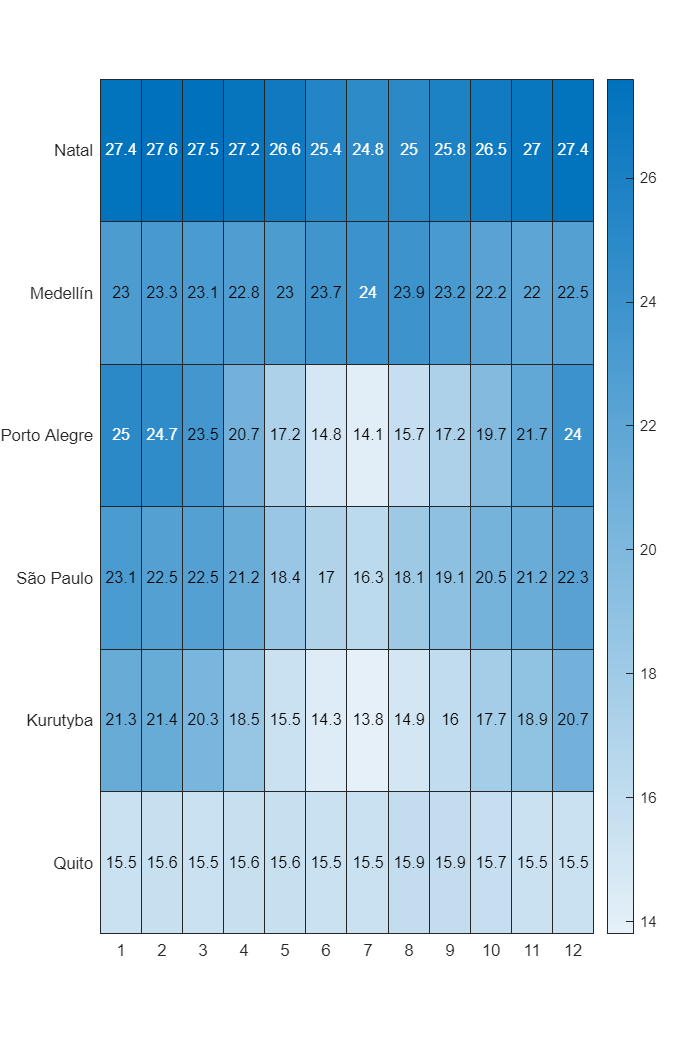

averages_table = readtable("averages.csv", "VariableNamesLine", 1, "ReadRowNames", true);
averages_table = averages_table([3, 2, 4, 6, 1, 5], :);

figure(2);
heatmap(1:12, averages_table.city, averages_table.Variables);

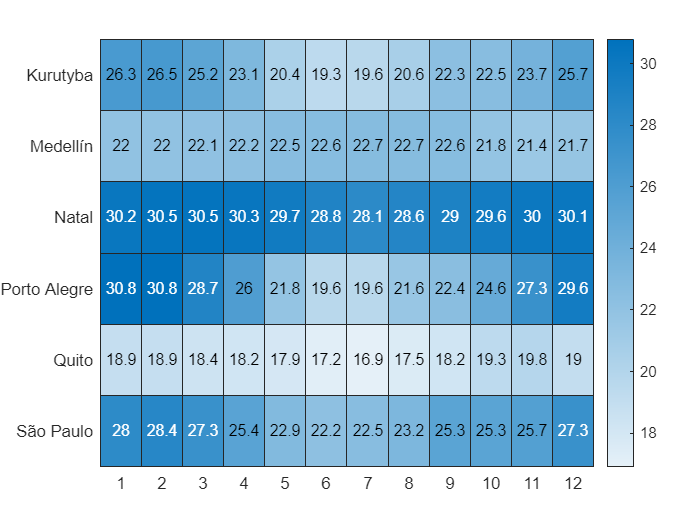

maximums_table = avg_maximums_month({brazil_curitiba, colombia_medellin, brazil_natal, brazil_portoalegre, ecuador_quito, brazil_saopaulo});

figure(3);
heatmap(1:12, cities, maximums_table);

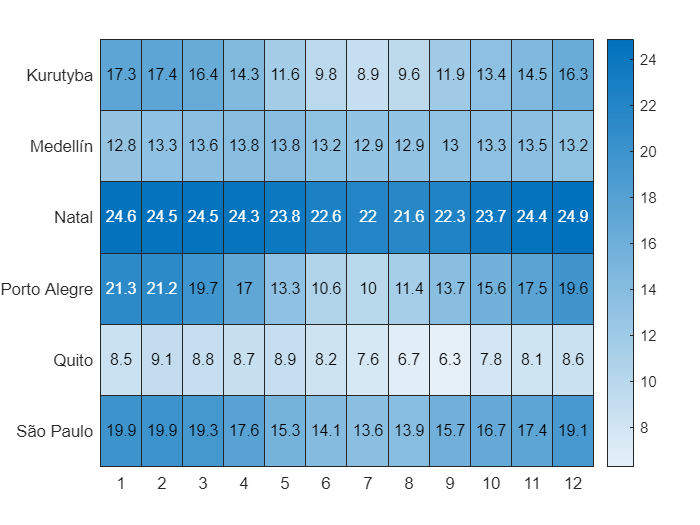

minimums_table = avg_minimums_month({brazil_curitiba, colombia_medellin, brazil_natal, brazil_portoalegre, ecuador_quito, brazil_saopaulo});

figure(4);
heatmap(1:12, cities, minimums_table);

#### Zestawienie maksymalnych i minimalnych temperatur w każdym mieście dla poszczególnych dni na wykresie biegunowym

Warto zaznaczyć: w zestawie danych pojawiają się dni przestępne 29 lutego. Zatem aby wyrównać lata przestępne ze zwykłymi, pominiemy ten dzień, jeśli się pojawi.

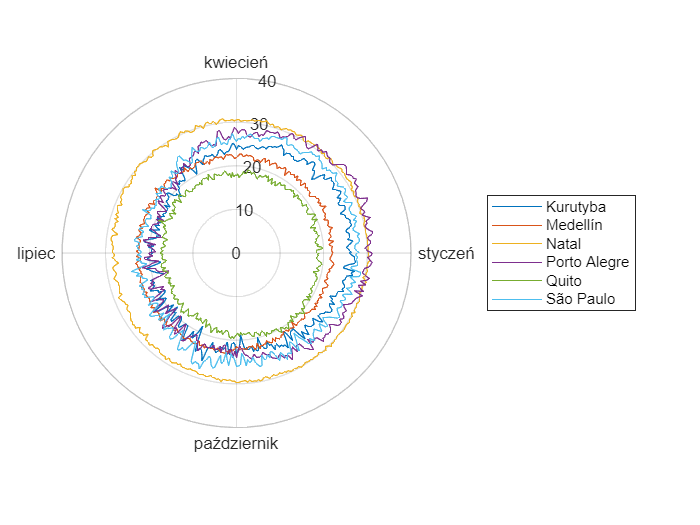

theta = linspace(0, 2*pi, 365);

maximums_bc = avg_maximums_day(brazil_curitiba);
maximums_cm = avg_maximums_day(colombia_medellin);
maximums_bn = avg_maximums_day(brazil_natal);
maximums_bp = avg_maximums_day(brazil_portoalegre);
maximums_eq = avg_maximums_day(ecuador_quito);
maximums_bs = avg_maximums_day(brazil_saopaulo);

figure(5);
pax = polaraxes;
hold(pax, 'on');

polarplot(theta, maximums_bc);
polarplot(theta, maximums_cm);
polarplot(theta, maximums_bn);
polarplot(theta, maximums_bp);
polarplot(theta, maximums_eq);
polarplot(theta, maximums_bs);

ax = gca;
ax.RLim = [0 40];
ax.ThetaTick = [0 90 180 270];
ax.ThetaTickLabel = {'styczeń', 'kwiecień', 'lipiec', 'październik'};

legend(cities);

hold(pax, 'off');